# Actividad 3.2: Pose y Velocidades Angulares

- **Daniel Castillo López A01737357**

- **Emmanuel Lechuga Arreola A01736241**

- **Paola Rojas Domínguez A01737136**

En este script se modela y simula el movimiento de un robot móvil diferencial que sigue una secuencia de velocidades lineales y angulares definidas como referencias. La simulación también incluye la visualización del movimiento en un entorno 3D, así como las gráficas correspondientes a las entradas de velocidad.

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear
close all
clc

## Trayectoria de cuadrado

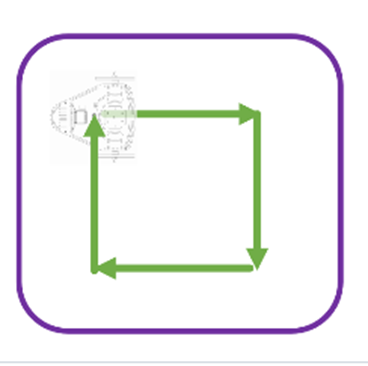

### Velocidades de referencia

Se comienza definiendo los vectores de referencia de velocidad. La velocidad lineal `u` alterna entre avanzar a 2 m/s durante 10 muestras y detenerse durante las siguientes 10, generando un patrón cíclico de movimiento. Por su parte, la velocidad angular `w` permanece en cero por 10 muestras y luego toma el valor constante de π/2 rad/s en las siguientes 10, produciendo giros de 90° en esos intervalos. Esta secuencia está pensada para simular un movimiento cuadrado en el plano.

u = [2*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2*ones(1,10), zeros(1, 10), 2*ones(1,10), zeros(1, 10)];
w = [zeros(1, 10), pi/2.*ones(1, 10),zeros(1,10), pi/2.*ones(1, 10), zeros(1,10), pi/2.*ones(1, 10),zeros(1,10), pi/2.*ones(1, 10)];  % Velocidad angular de referencia (rad/s)

### Tiempo

A continuación, se establecen los parámetros temporales. El número de muestras `N` se obtiene a partir de la longitud del vector `u`, mientras que el tiempo de muestreo se define como `ts = 0.1` segundos. El vector de tiempo `t` se genera con una distribución lineal.

N = length(u);
tf = N*2;
ts = 0.1;
t = linspace(0, ts, N);

### Condiciones iniciales

Las condiciones iniciales del robot se fijan en el origen del plano, con orientación cero. Los vectores `x1`, `y1` y `phi` representan respectivamente la posición en el eje X, el eje Y y la orientación del robot a lo largo de toda la simulación.

x1 = zeros (1,N+1);
y1 = zeros (1,N+1);
phi = zeros(1, N+1);

Todos ellos se inicializan en cero, asignando los valores iniciales explícitamente en la primera posición de cada vector. 

x1(1) = 0;
y1(1) = 0;
phi(1) = 0;

### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx = zeros(1, N+1);
hy = zeros(1, N+1);

hx(1) = x1(1);
hy(1) = y1(1);

### Bucle de simulación

El bucle `for` que recorre todas las muestras temporales. En cada iteración, se actualiza la orientación `phi` del robot utilizando integración numérica con el método de Euler. Luego, se calculan las componentes de la velocidad en los ejes X y Y considerando la orientación recién calculada. Con esas velocidades, también mediante Euler, se actualiza la posición del robot. Finalmente, se actualiza la trayectoria del punto de control con las nuevas coordenadas del centro del robot.

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([15 15]); % Orientacion de la figura
axis([-3 11 -3 10 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

#### b) Graficar robots en la posicion inicial

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

#### c) Graficar Trayectorias

H2=plot3(hx(1),hy(1),0,'c','lineWidth',2);

#### d) Bucle de simulacion de movimiento del robot

Se dibuja el robot en su posición inicial mediante una función externa (`MobilePlot_4`) que toma como parámetros la posición, orientación y una escala de visualización. Luego, se dibuja la primera parte de la trayectoria del punto de control en color rojo. El bucle de simulación gráfica recorre los pasos definidos, actualizando la posición del robot y su trayectoria en cada iteración.

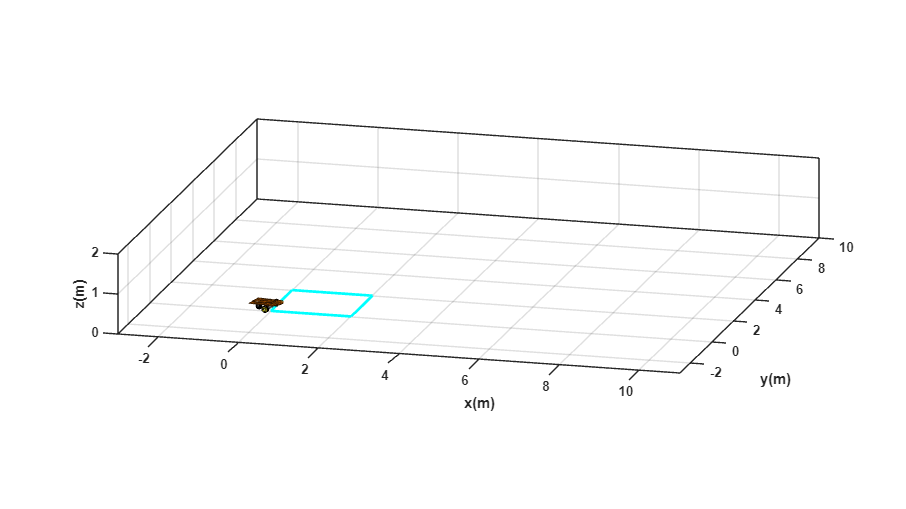

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'c','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se muestran las gráficas de las velocidades `u` y `w` a lo largo del tiempo. Se usan subplots para presentar ambas curvas por separado, manteniendo una línea clara y visible. Estas gráficas permiten verificar que las referencias de velocidad se aplicaron correctamente a lo largo de la simulación.

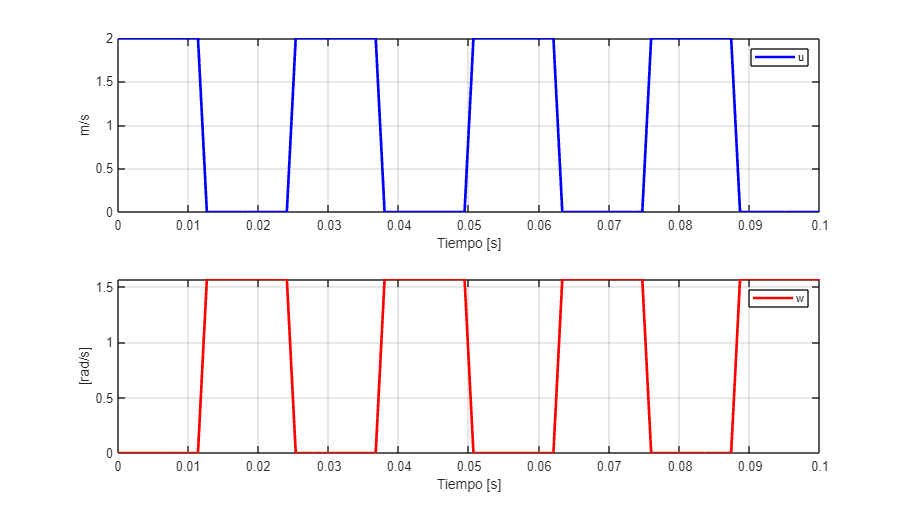

graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

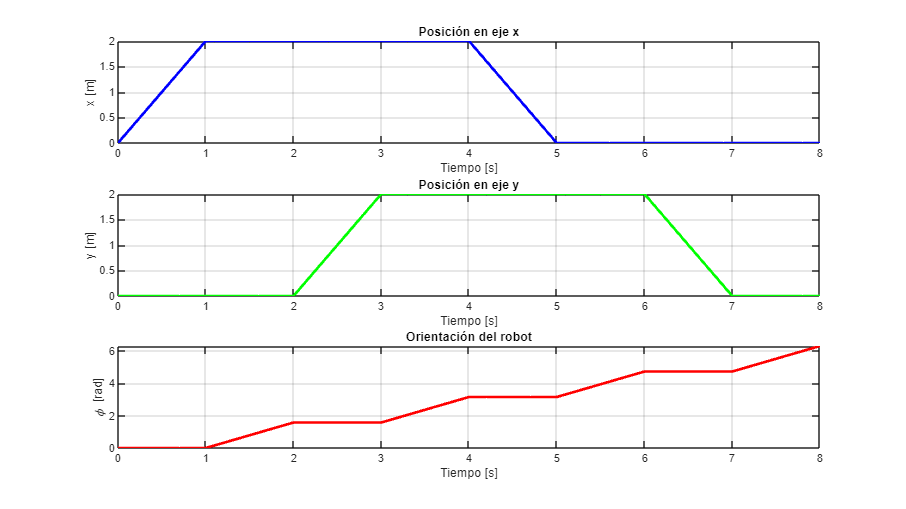

graph2 = figure;
set(graph2, 'position', sizeScreen);
subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;
subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;
subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;

## Trayectoria de zig zag

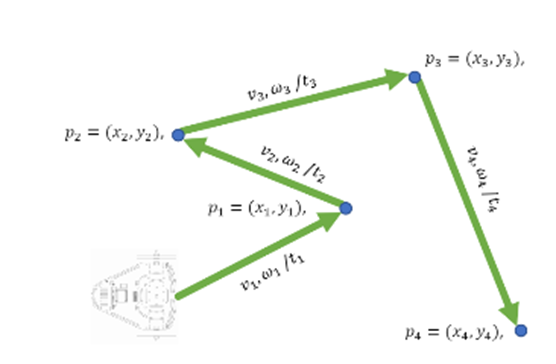

### Velocidades de referencia

Se definen las velocidades de referencia para controlar el movimiento del robot. La velocidad lineal `u` alterna entre pausas y tramos en movimiento, con velocidades de 1, 2 y hasta 4 m/s, lo que genera trayectos rectos de distinta longitud. La velocidad angular `w`, expresada en radianes, introduce giros específicos en los momentos en que el robot está detenido, con valores de ±45°, ±100° y ±120°, provocando cambios bruscos de orientación.

u = [zeros(1,10),2*ones(1, 10), zeros(1, 10), 1*ones(1, 10), zeros(1, 10), 2*ones(1,10), zeros(1, 10), 4*ones(1,10)];
w = [deg2rad(45).*ones(1, 10),zeros(1,10), deg2rad(100).*ones(1, 10), zeros(1,10), deg2rad(-120).*ones(1, 10),zeros(1,10), deg2rad(-100).*ones(1, 10),zeros(1,10)];

### Tiempo

A continuación, se establecen los parámetros temporales. El número de muestras `N` se obtiene a partir de la longitud del vector `u`, mientras que el tiempo de muestreo se define como `ts = 0.1` segundos. El vector de tiempo `t` se genera con una distribución lineal.

N = length(u);
tf = N*2;
ts = 0.1;
t = linspace(0, ts, N);

### Condiciones iniciales

Las condiciones iniciales del robot se fijan en el origen del plano, con orientación cero. Los vectores `x1`, `y1` y `phi` representan respectivamente la posición en el eje X, el eje Y y la orientación del robot a lo largo de toda la simulación.

x1 = zeros (1,N+1);
y1 = zeros (1,N+1);
phi = zeros(1, N+1);

Todos ellos se inicializan en cero, asignando los valores iniciales explícitamente en la primera posición de cada vector. 

x1(1) = 0;
y1(1) = 0;
phi(1) = 0;

### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx = zeros(1, N+1);
hy = zeros(1, N+1);

hx(1) = x1(1);
hy(1) = y1(1); 

### Bucle de simulación

El bucle `for` que recorre todas las muestras temporales. En cada iteración, se actualiza la orientación `phi` del robot utilizando integración numérica con el método de Euler. Luego, se calculan las componentes de la velocidad en los ejes X y Y considerando la orientación recién calculada. Con esas velocidades, también mediante Euler, se actualiza la posición del robot. Finalmente, se actualiza la trayectoria del punto de control con las nuevas coordenadas del centro del robot.

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([15 15]); % Orientacion de la figura
axis([-3 11 -3 10 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]


#### b) Graficar robots en la posicion inicial

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

#### c) Graficar Trayectorias

H2=plot3(hx(1),hy(1),0,'c','lineWidth',2);

#### d) Bucle de simulacion de movimiento del robot

Se dibuja el robot en su posición inicial mediante una función externa (`MobilePlot_4`) que toma como parámetros la posición, orientación y una escala de visualización. Luego, se dibuja la primera parte de la trayectoria del punto de control en color rojo. El bucle de simulación gráfica recorre los pasos definidos, actualizando la posición del robot y su trayectoria en cada iteración.

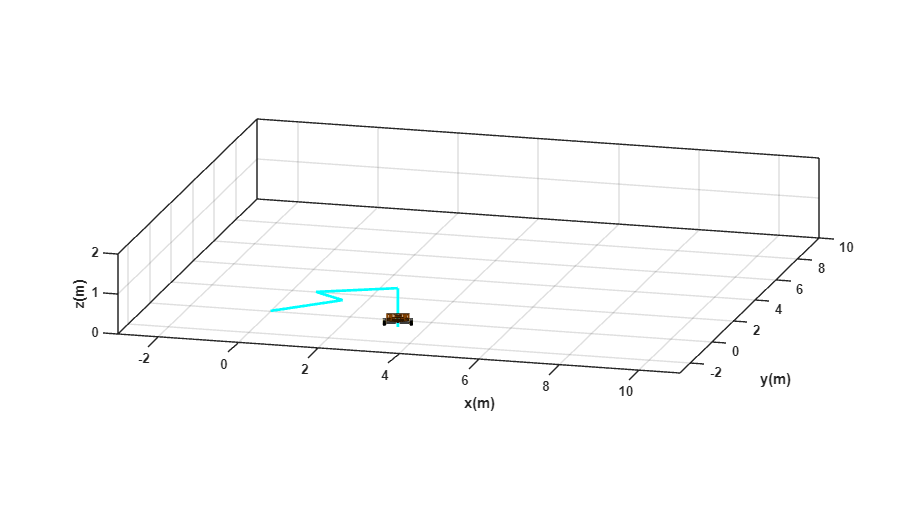

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'c','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se muestran las gráficas de las velocidades `u` y `w` a lo largo del tiempo. Se usan subplots para presentar ambas curvas por separado, manteniendo una línea clara y visible. Estas gráficas permiten verificar que las referencias de velocidad se aplicaron correctamente a lo largo de la simulación.

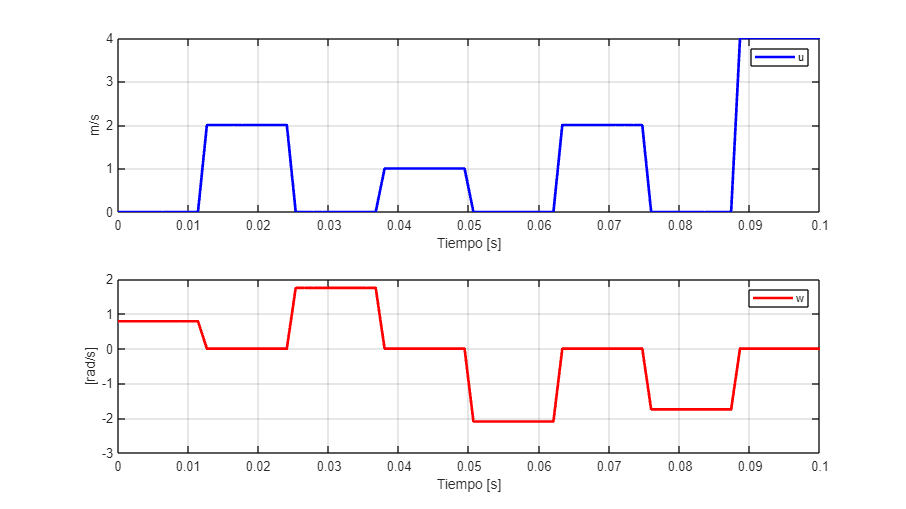

graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(2,1,1)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(2,1,2)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

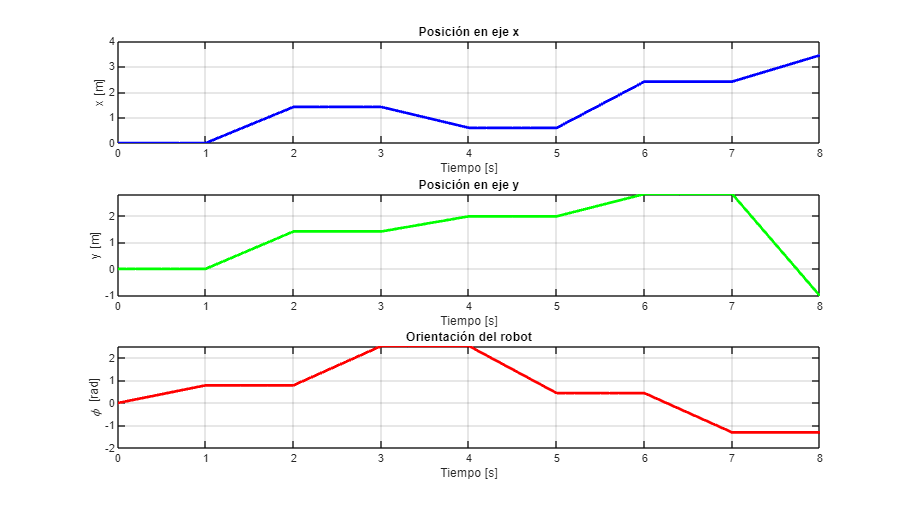

graph2 = figure;
set(graph2, 'position', sizeScreen);
subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;
subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;
subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;